Calculates the normalized active force in muscle fibers with respect to the active force-length relationship (applies to all muscles in OpenSim musckuloskeletal model)

${\overset{~}{l} }^M$ is the normalized muscle fiber length

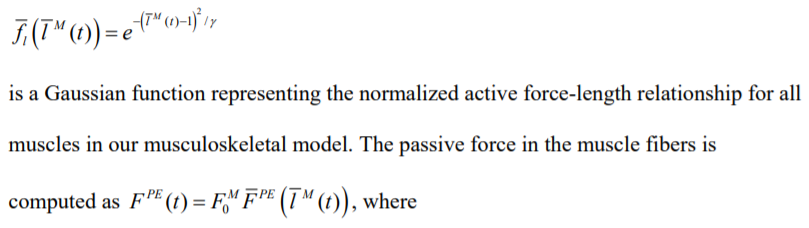

function F_L = Thelen2003_Active_Force_Length(fib_len)
    % 0.5 in documentation, however, a value of 1 gives correct value at
    % optimal length
    gamma = 1;% a shape factor for the Gaussian active force-length relationship
    F_L = zeros(size(fib_len));
    for i = 1:length(fib_len)
        lM = fib_len(i);
        F_L(i) = exp(-(lM - 1).^2)/gamma;
    end
end